clear all
h_inf_flight = 0;       % unk
v_inf_flight = 7483;    % m/s


userpath('D:\Files\Uni\2022\Capstone\Capstone-code\MATLAB analysis\Boundary conditions')    %set file path

t = 0:1:250    % set global timestep for plotting, s

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


## Import data

## (Note assumes ideal gas)



% import surface temperature data
surface_temperatures = readmatrix('pathfinder_temperatures.csv');

% import velocity/time data
import = readmatrix('pathfinder_velocity_profile.csv');
velocity_raw = import(:,2)  ;
velocity_timestep_raw = import(:,1);

velocity_interpolated = interp1(velocity_timestep_raw,velocity_raw,t).*1000 % interpolated velocity in global timestep,m/s

velocity_interpolated = 	1.0e+03 *

    7.4642    7.4642    7.4642    7.4642    7.4642    7.4642    7.4642    7.4642    7.4657    7.4689    7.4720    7.4752    7.4784    7.4815    7.4840    7.4853    7.4865    7.4877    7.4889    7.4902    7.4914    7.4926    7.4939    7.4951    7.4963    7.4976    7.4988    7.5000    7.5013    7.5025    7.5030    7.5030    7.5030    7.5030    7.5030    7.5030    7.5026    7.4989    7.4952    7.4915    7.4878    7.4841    7.4779    7.4712    7.4645    7.4579    7.4512    7.4443    7.4234    7.4025


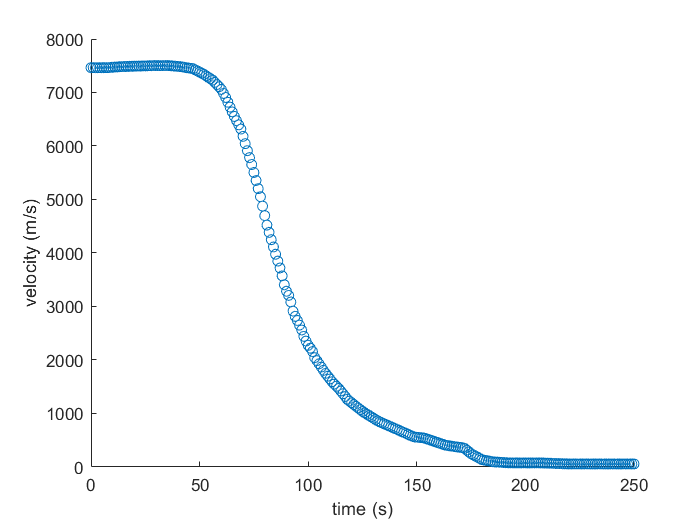


scatter(t,velocity_interpolated)
xlabel("time (s)")
ylabel("velocity (m/s)")

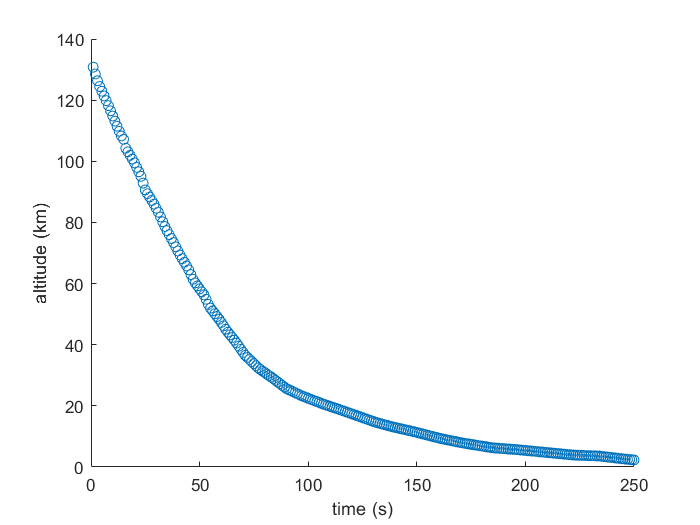


% import altitude/time data
import = readmatrix('pathfinder_altitude_profile.csv');
altitude_raw = import(:,2);
altitude_timestep_raw = import(:,1);
altitude_interpolated = interp1(altitude_timestep_raw, altitude_raw, t); % interpolated altitude in global timestep km

scatter(t, altitude_interpolated)
xlabel('time (s)');
ylabel('altitude (km)');

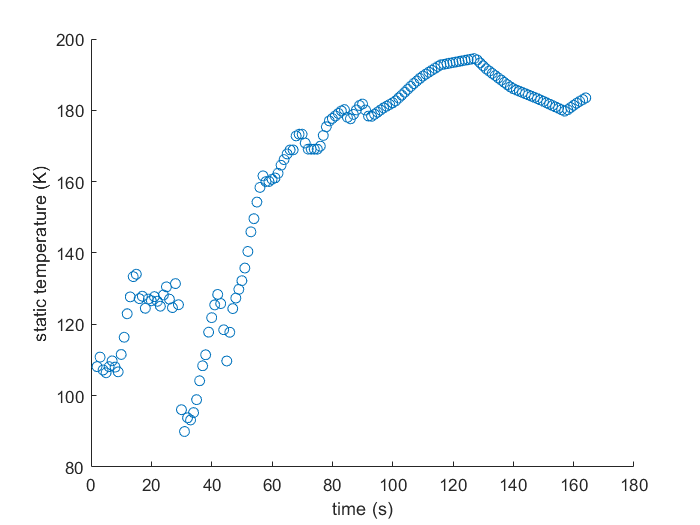


% import altitude/temperature data
import = readmatrix('pathfinder_temperature_with_altitude_profile.csv');
altitude_temp_raw = import(:,2); % altitude for temp data
temperature_raw = import(:,1);  % temp for temp data
temperature_interpolated = interp1(altitude_temp_raw, temperature_raw, altitude_interpolated); % interpolated altitude in global timestep km

scatter(t, temperature_interpolated)
xlabel('time (s)');
ylabel('static temperature (K)');


% determine density
density_flight = zeros([1,length(t)]);
for i = 1:length(t)
    density_flight(i) = density_at_altitude(altitude_interpolated(i));
end
density_flight

density_flight =        NaN    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0004    0.0005    0.0006    0.0008    0.0010    0.0013    0.0017    0.0023    0.0027    0.0031    0.0038    0.0044    0.0074    0.0100    0.0130    0.0188    0.0249    0.0313    0.0373    0.0434    0.0530    0.0632    0.0735    0.0950    0.1197    0.1443    0.1689    0.2066    0.2569    0.3073    0.3533    0.4039


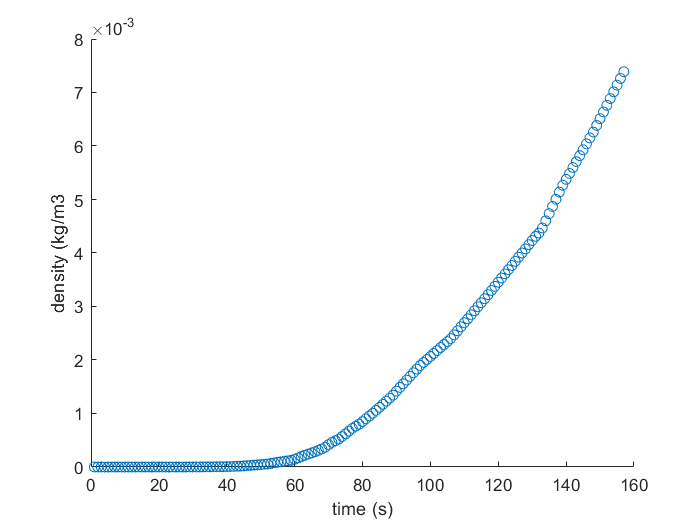

scatter(t, density_flight)
xlabel('time (s)');
ylabel('density (kg/m3');


% determine atmospheric pressure at time 
M = 43.2685; % mean molecular weight, kg/kmol
R = 8314.34;    % universal gas constant, J/kmol*K
% p = T*density*R/M
atmospheric_pressure = temperature_interpolated.*density_flight.*R./M

atmospheric_pressure =        NaN       NaN    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0004    0.0005    0.0008    0.0009    0.0011    0.0013    0.0015    0.0019    0.0024    0.0030    0.0043    0.0058    0.0065    0.0075    0.0095    0.0107    0.0136    0.0173    0.0233    0.0337    0.0456    0.0594    0.0747    0.0903    0.1134    0.1431    0.1720    0.2291    0.2952    0.3488    0.3844    0.4355    0.5815    0.7347    0.8646    1.0074


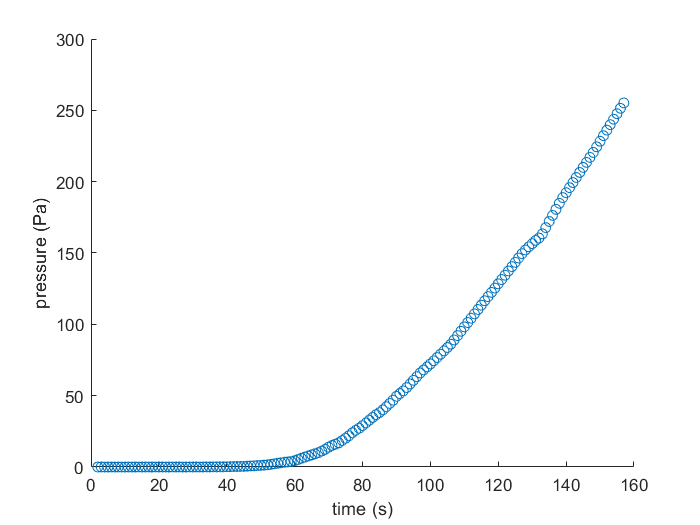


scatter(t, atmospheric_pressure)
xlabel('time (s)');
ylabel('pressure (Pa)');


%{
h_stagnation_ground = 0.5.*velocity_interpolated.^2;
p_stagnation_ground = density_flight.*velocity_interpolated.^2;

%determine mach number via ideal gas
gamma = 1.333; %CO2
M = (gamma.*R.*temperature_interpolated).^0.5
scatter(t, M)
xlabel('time (s)');
ylabel('Mach number');
%}

%{
yyaxis left
plot(t,h_stagnation_ground./1000000)
xlim([0 150])
xlabel('time (s)')
ylabel('h_0 ground (MJ/kg)')
hold on
yyaxis right
plot(t,p_stagnation_ground./1000)
hold on
%fill([],[],'r','FaceAlpha',0.2)
xlabel('time (s)')
ylabel('p_0 ground (kPa)')
hold off
%}

plot(h_stagnation_ground./1000000,p_stagnation_ground)

Undefined function or variable 'h_stagnation_ground'.

set(gca, 'YScale','log', 'Ydir','reverse')
xlabel('h_0 ground (MJ/kg)')
ylabel('p_0 ground (Pa)')
yticks([1 10 100 1000 10000 100000 1000000])
ylim([1 1000000])
hold on
fill([2.5   15  25   25  11   0.5  1.25],...
     [0.04  0.1 0.15 0.6 0.95 0.15 0.06].*1000000, 'g', 'FaceAlpha',1)
 %fill([25 30 30 25],[0.15 0.15 0.6 0.6].*1000000,'g', 'FaceAlpha',0.2)
legend("Pathfinder trajectory", "Uni-BwM plasma wind tunnel capabiltiy (M3.5 nozzle, CO_2)",'location','southoutside')
title('Uni-BwM plasma wind tunnel compatability for scaled Pathfinder simulation')
hold off

time_of_interest = 75; % 75 s is time of max heat flux

%print('Time of interest is ' + num2str(time_of_interest) + ' seconds')
time_of_interest = time_of_interest + 1;
h_stagnation_ground(time_of_interest)
p_stagnation_ground(time_of_interest)
atmospheric_pressure(time_of_interest)
temperature_interpolated(time_of_interest)
velocity_interpolated(time_of_interest)
%{
print(  'At this time, conditions are:')
print(                'Stagnation entalpy = ' + num2str(h_stagnation_ground(time_of_interest)) + 'J/kg')
print(                'Stagnation temperature = '+ num2str(p_stagnation_ground(time_of_interest)) + 'Pa')
print(                'Atmospheric pressure = '+ num2str(atmospheric_pressure(time_of_interest)) + 'Pa')
print(                'Atmospheric temperature = ' + num2str(temperature_interpolated(time_of_interest)) + 'K' )
%}



function density = density_at_altitude(km) 
    % import density at altitude
    import = readmatrix('pathfinder_density_at_altitude.csv');
    density_raw = import(:,1); % kg/km^3
    density_altitude_raw = import(:, 2); % km    
    density = interp1(density_altitude_raw,density_raw,km)/(1000^3); %interpolate and convert to kg/m3
    
end
